# MAE 232A: Computer assignment 1

#### **By** - Nandan Seshadri (A59018150)

close; clc; clear;

## Pre-processing

### `Preprocessing: Inputs`

[nEle, Omega, A, E, h] = Input();

### `Preprocessing: Discretization`

[NEN, nNodes, LM] = Discretization(nEle);
xI = linspace(Omega(1), Omega(2), nNodes);

## Processing

### `Processing: Stiffness Matrix and Force Vector Evaluation and Assembly`

% Initialize global stiffness matrix and force vector
K_global = zeros(nNodes);
f_Q_global = zeros(nNodes,1);
f_h_global = zeros(nNodes,1);
f_global = zeros(nNodes,1);

% Gather Gauss Integration information
nGP = 2; % Number of Gauss points, scalar
IP = [-0.57, 0.57]; % Integration point locations, 1 x nGP array
WT = [1.0, 1.0]; % Gauss weights, 1 x nGP array

% Define the shape functions for a linear element
N1 = 0.5 * (1 - IP);
N2 = 0.5 * (1 + IP);

% Define the derivative of the shape functions
dN1_dx = -0.5;
dN2_dx = 0.5;

for e = 1:nEle % Loop over elements
    % Gather Nodal Information
    node1 = LM(e,2); % Node numbers
    node2 = LM(e,3);
    x_1 = xI(node1); % x-position of nodes
    x_2 = xI(node2);
    xEle = [x_1; x_2]; % Vector with x-position of nodes
    l_e = x_2-x_1; % Element length

    % Initialize local K matrix and f vectors
    K_local = zeros(NEN);
    f_Q_local = zeros(NEN,1);
    f_h_local = zeros(NEN,1);

    for ii = 1:nGP % Loop over Gauss Integration Points
%       Evaluate Shape Function Vector and Gradient Matrix
        xi = (N1(ii)*x_1) + (N2(ii)*x_2);

        % Calculate the derivative of the shape functions with respect to xi
        B_psi = 2/l_e .*[dN1_dx; dN2_dx];

        % Create the local stiffness matrix and force vector using Gauss Integration
        K_local = K_local + A*E .* B_psi' .* B_psi .* (l_e/2) .* WT(ii);
        f_Q_local = f_Q_local + l_e/2 * [N1(ii); N2(ii)] * sin(pi*xi/10) * WT(ii);
    end

    % Apply NBC to the appropriate f_h_local
    if e == 1
        f_h_local = -A*h*[1;0]; % Natural boundary flux at right side (negative sign)
    else
        f_h_local = zeros(NEN,1);
    end

    % Assembly, Map local to global
    % Global stiffness matrix
    c1(e) = {K_local};
    K_global(e:e+1,e:e+1) = K_global(e:e+1,e:e+1) + c1{e};

    % f_Q_global matrix
    c2(e) = {f_Q_local};
    f_Q_global(e:e+1,1) = f_Q_global(e:e+1,1) + c2{e};


    % f_h_global matrix
    c3(e) = {f_h_local};
    f_h_global(e:e+1,1) = f_h_global(e:e+1,1) + c3{e};

    % Global force vector 
    f_global = f_Q_global + f_h_global;
end

### `Processing: Solve System Matrix Equation, Find Nodal Coefficients`

% Apply Dirichlet BCs and obtain modified global stiffness matrix and force vector
K_ng = K_global(1:end-1, 1:end-1);
f_ng = f_global(1:end-1, :);
u_app = K_ng\f_ng; % Solve for nodal coefficients u
u_app(end+1) = 0;

## `Results`

disp(K_global)      % Global stiffness matrix

     2    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -2     4    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -2     4    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -2     4    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -2     4    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -2     4    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -2     4    -2     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -2     4    -2     0     0     0     0     0     0     0     0     0   

disp(f_Q_global)

    0.0132
    0.0781
    0.1542
    0.2265
    0.2933
    0.3528
    0.4037
    0.4446
    0.4745
    0.4928
    0.4990
    0.4928
    0.4745
    0.4446
    0.4037
    0.3528
    0.2933
    0.2265
    0.1542
    0.0781
    0.0132



disp(f_h_global)

   -3.1831
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



disp(f_global)      % Global displacement matrix 

   -3.1699
    0.0781
    0.1542
    0.2265
    0.2933
    0.3528
    0.4037
    0.4446
    0.4745
    0.4928
    0.4990
    0.4928
    0.4745
    0.4446
    0.4037
    0.3528
    0.2933
    0.2265
    0.1542
    0.0781
    0.0132



disp(u_app)         % Finite element solutions

    0.0008
    1.5858
    3.1317
    4.6005
    5.9560
    7.1649
    8.1974
    9.0281
    9.6365
   10.0076
   10.1323
   10.0075
    9.6363
    9.0278
    8.1971
    7.1645
    5.9555
    4.5999
    3.1310
    1.5850
         0



## Postprocessing: Plot Numerical Results

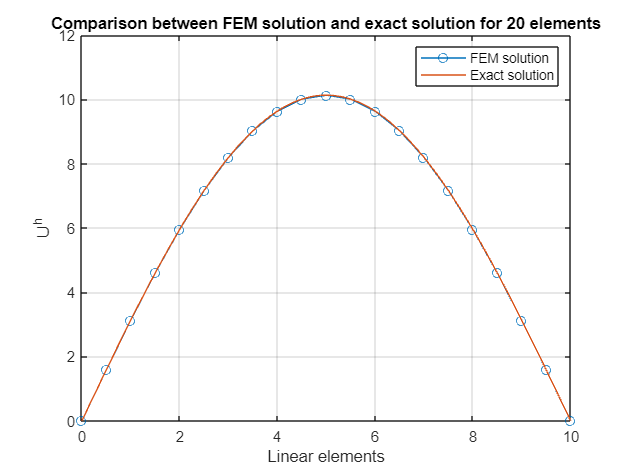

% Using the exact solution to calculate error
syms x
u_exact = (100/pi.^2).*sin((pi*x)/10);

% Plotting mesh results with exact solution
plot(xI, u_app', '-o')
hold on;
fplot(u_exact, [0, 10])
legend("FEM solution", "Exact solution")
xlabel("Linear elements")
ylabel("U^h")
title("Comparison between FEM solution and exact solution for "+ nEle + " elements")
grid on
hold off;

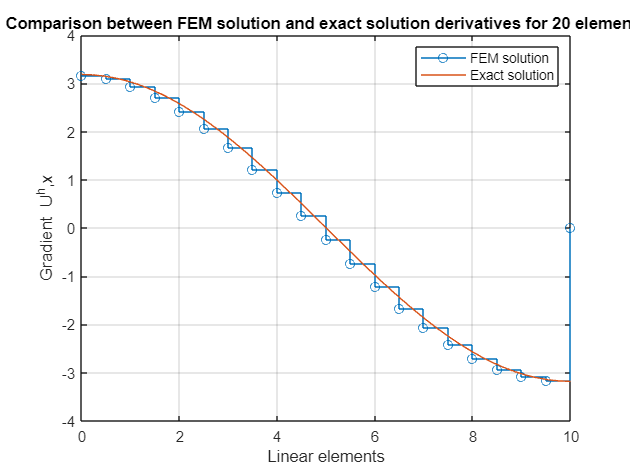

% Obtaining the derivative of the exact solution
ux_exact = diff(u_exact);
ux_app = zeros(length(u_app)-1, 1);
for j = 2:length(u_app)
    ux_app(j-1) = (u_app(j) - u_app(j-1))/l_e;
end
ux_app = [ux_app', 0]';

% Plot element-wise
stairs(xI, ux_app, '-o')
hold on
fplot(ux_exact,[0, 10])
legend("FEM solution", "Exact solution")
xlabel("Linear elements")
ylabel("Gradient U^h,x")
title("Comparison between FEM solution and exact solution derivatives for "+ nEle + " elements")
grid on
hold off

## `Input function`

function [nEle, Omega, A, E, h] = Input()
% Outputs:
    % nEle = number of elements
    % Omega = 1x2 array of domain position [m]
    % E = stiffness (young's modulus)
    % h = load
    % A = cross sectional area [m^2]

% Mesh
% nEle = 5;   % Number of finite elements = 5
% nEle = 10;  % Number of finite elements = 10
nEle = 20;  % Number of finite elements = 20
% Geometry
A = 1.0;
Omega = [0; 10]; % [left_edge right_edge]
% Material Properties
E = 1;
% Loading
h = 10/pi;
end

## `Discretisation function`

function [NEN, nNodes, LM] = Discretization(nEle)

% Inputs:
    % nEle = number of elements
% Outputs:
    % NEN = number of element nodes
    % nNodes = number of total nodes
    % LM = location matrix, nEle x (NEN + 1) array

% Discretization
NEN = 2; % Number of element nodes
nNodes = nEle + 1;

LM = zeros(nEle,3); % Initialize location matrix
LM(1,:) = [1 1 2];
    for i = 2:nEle
        LM(i,:) = LM(i-1, :) +1; % Populate location matrix row [eleID nodeID1 nodeID2 ... nodeIDn]  
    end
end

**Note:** Generative AI was used for debugging purposes only